
w=0.05

w = 0.0500

r0=5000

r0 = 5000

A=[0 1 0 0;
    3*w^2 0 0 2*w*r0;
    0 0 0 1;
    0 (-2*w)/r0 0 0]

A =          0    1.0000         0         0
    0.0075         0         0  500.0000
         0         0         0    1.0000
         0   -0.0000         0         0


B=[0 0;
    0 2;
    0 0;
    -0.01 0]

B =          0         0
         0    2.0000
         0         0
   -0.0100         0


C=eye(4,4);
C1=[0 0 0 0;
    0 0 0 0;
    0 0 1 0;
    0 0 0 0];
D=zeros(4,2);


sys = ss(A,B,C,D)

sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2  0.0075       0       0     500
   x3       0       0       0       1
   x4       0  -2e-05       0       0
 
  B = 
          u1     u2
   x1      0      0
   x2      0      2
   x3      0      0
   x4  -0.01      0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.



[b,a] = ss2tf(A,B,C,D,2)

b =          0         0    2.0000         0         0
         0    2.0000         0         0         0
         0         0         0   -0.0000         0
         0         0   -0.0000         0         0


a =     1.0000         0    0.0025         0         0


tf(sys)

ans =
 
  From input 1 to output...
             -5
   1:  --------------
       s^3 + 0.0025 s
 
            -5 s
   2:  --------------
       s^3 + 0.0025 s
 
       -0.01 s^2 - 1.388e-19 s + 7.5e-05
   3:  ---------------------------------
               s^4 + 0.0025 s^2
 
       -0.01 s^2 + 1.388e-19 s + 7.5e-05
   4:  ---------------------------------
                s^3 + 0.0025 s
 
  From input 2 to output...
            2 s
   1:  --------------
       s^3 + 0.0025 s
 
           2 s^2
   2:  --------------
       s^3 + 0.0025 s
 
           -4e-05 s
   3:  ----------------
       s^4 + 0.0025 s^2
 
          -4e-05 s
   4:  --------------
       s^3 + 0.0025 s
 
Continuous-time transfer function.




% Co = ctrb(A,B)
Co = ctrb(sys)

Co =          0         0         0    2.0000   -5.0000         0         0   -0.0050
         0    2.0000   -5.0000         0         0   -0.0050    0.0125         0
         0         0   -0.0100         0         0   -0.0000    0.0001         0
   -0.0100         0         0   -0.0000    0.0001         0         0    0.0000


unco = length(A) - rank(Co)

unco = 0


Ob= obsv(A,C)

Ob =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000
         0    1.0000         0         0
    0.0075         0         0  500.0000
         0         0         0    1.0000
         0   -0.0000         0         0
    0.0075         0         0  500.0000
         0   -0.0025         0         0


% Number of unobservable states
unob = length(A)-rank(Ob)

unob = 0


% P = pole(sys);
Apoles = eig(A)

Apoles =    0.0000 + 0.0000i
   0.0000 + 0.0500i
   0.0000 - 0.0500i
   0.0000 + 0.0000i



% State-Feedback Gain Selection
p=[-2+i*2;-2-i*2;-1;-1]

p =   -2.0000 + 2.0000i
  -2.0000 - 2.0000i
  -1.0000 + 0.0000i
  -1.0000 + 0.0000i


K = place(A,B,p)

K =  -800.0000 -799.9980 -400.0000 -500.0000
    0.0037    0.5000   -0.5000  249.5000


P = pole(sys)

P =    0.0000 + 0.0000i
   0.0000 + 0.0500i
   0.0000 - 0.0500i
   0.0000 + 0.0000i


plant = (A-B*K)

plant =          0    1.0000         0         0
    0.0000   -1.0000    1.0000    1.0000
         0         0         0    1.0000
   -8.0000   -8.0000   -4.0000   -5.0000


poles_cl = eig(plant)

poles_cl =   -2.0000 + 2.0000i
  -2.0000 - 2.0000i
  -1.0000 + 0.0000i
  -1.0000 + 0.0000i





des_poles = (min(real(poles_cl))*3)-(1:4); %This is better
des_poles

des_poles =    -7.0000   -8.0000   -9.0000  -10.0000


K = place(A,B,des_poles)

K = 	1.0e+03 *

    0.7791    0.0918   -6.9333   -1.6740
    0.0368    0.0086   -0.0043    0.2495


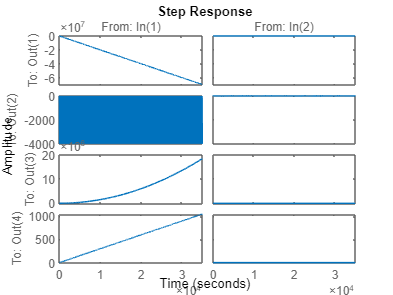

step(sys);





sys2=ss(A-B*K,B,C,D)

sys2 =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2  -73.67  -17.26   8.653   1.013
   x3       0       0       0       1
   x4   7.791  0.9185  -69.33  -16.74
 
  B = 
          u1     u2
   x1      0      0
   x2      0      2
   x3      0      0
   x4  -0.01      0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.




%c1=feedback(sys,K); % same as line upside

tf(sys2)

ans =
 
  From input 1 to output...
                -0.01013 s - 0.08653
   1:  --------------------------------------
       s^4 + 34 s^3 + 431 s^2 + 2414 s + 5040
 
        -0.01013 s^2 - 0.08653 s - 2.918e-17
   2:  --------------------------------------
       s^4 + 34 s^3 + 431 s^2 + 2414 s + 5040
 
           -0.01 s^2 - 0.1726 s - 0.7367
   3:  --------------------------------------
       s^4 + 34 s^3 + 431 s^2 + 2414 s + 5040
 
         -0.01 s^3 - 0.1726 s^2 - 0.7367 s
   4:  --------------------------------------
       s^4 + 34 s^3 + 431 s^2 + 2414 s + 5040
 
  From input 2 to output...
              2 s^2 + 33.48 s + 138.7
   1:  --------------------------------------
       s^4 + 34 s^3 + 431 s^2 + 2414 s + 5040
 
            2 s^3 + 33.48 s^2 + 138.7 s
   2:  --------------------------------------
       s^4 + 34 s^3 + 431 s^2 + 2414 s + 5040
 
                  1.837 s + 15.58
   3:  --------------------------------------
       s^4 + 34 s^3 + 431 s^2 + 2414 s + 5040
 


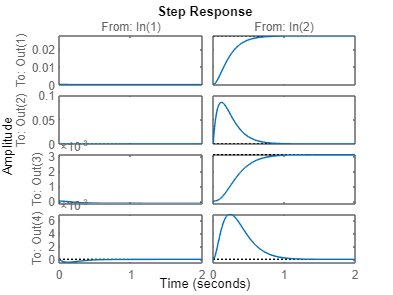

step(sys2)

Kdc=dcgain(sys2);

% Nbar = rscale(sys,K)


% State Estimator Design (Observer)

%obspol = [-1+2i*2;-1-2i*2;-0.2;-0.2] % example for desired poles


L=place(A.',C.',des_poles)

L =     7.0000    0.0075         0         0
    1.0000    8.0000         0   -0.0000
         0         0    9.0000         0
         0  500.0000    1.0000   10.0000


obsplant=(A-L*C)

obsplant =    -7.0000    0.9925         0         0
   -0.9925   -8.0000         0  500.0000
         0         0   -9.0000    1.0000
         0 -500.0000   -1.0000  -10.0000


poles_obs=eig(obsplant)

poles_obs = 	1.0e+02 *

  -0.0900 + 5.0000i
  -0.0900 - 5.0000i
  -0.0700 + 0.0000i
  -0.0900 + 0.0000i


des_poles1 = (min(real(poles_obs))*3)-(1:4); %This is better
des_poles1

des_poles1 =   -28.0000  -29.0000  -30.0000  -31.0000





% Ke= acker(A.', C.', L)
% Ket=L.'

Aobs = [A-L*C]

Aobs =    -7.0000    0.9925         0         0
   -0.9925   -8.0000         0  500.0000
         0         0   -9.0000    1.0000
         0 -500.0000   -1.0000  -10.0000


Bobs = [B L]

Bobs =          0         0    7.0000    0.0075         0         0
         0    2.0000    1.0000    8.0000         0   -0.0000
         0         0         0         0    9.0000         0
   -0.0100         0         0  500.0000    1.0000   10.0000


% Aobs= A-Ket*C-B*K
% Bobs=L
Cobs=[0 0 0 0;
    0 0 0 0;
    0 0 1 0;
    0 0 0 0];

Cobs1=[1.1 0 0 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1];

Dobs = zeros(4,6);


% G= -inv(C*inv(A-B*K)*B)


% q=[-1+i*2;-1-i*2;-2;-3]
% L = place(A',C',q);




% controls = [2];
% sensors = [1];
% known = [1];
% regulator = reg(sys,K,L,sensors,known,controls)


%%%LQR 1%%%
Q =[1 0 0 0;
 0 1 0 0;
 0 0 1 0;
 0 0 0 1]

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


R =eye(2)

R =      1     0
     0     1


N=0;
[Klqr,S,E]=lqr(A,B,Q,R,N)

Klqr =    -0.4230   -0.7254   -0.9061 -227.3233
    0.9099    1.1750   -0.4230  145.0888


S = 	1.0e+04 *

    0.0001    0.0000    0.0000    0.0042
    0.0000    0.0001   -0.0000    0.0073
    0.0000   -0.0000    0.0250    0.0091
    0.0042    0.0073    0.0091    2.2732


E =   -0.0040 + 0.0000i
  -0.9789 + 0.0000i
  -1.8202 + 1.3397i
  -1.8202 - 1.3397i



Nbar= -pinv(C*inv(A-B*Klqr)*B);
G=Nbar;

plant_lqr = (A-B*Klqr)

plant_lqr =          0    1.0000         0         0
   -1.8123   -2.3501    0.8460  209.8224
         0         0         0    1.0000
   -0.0042   -0.0073   -0.0091   -2.2732


poles_lqr = eig(plant_lqr)

poles_lqr =   -1.8202 + 1.3397i
  -1.8202 - 1.3397i
  -0.9789 + 0.0000i
  -0.0040 + 0.0000i



%%%LQR 2%%%
Q2 =[100 0 0 0;
 0 1 0 0;
 0 0 1 0;
 0 0 0 1]

Q2 =    100     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


R2 =eye(2)

R2 =      1     0
     0     1


N2=0;
[Klqr2,S2,E2]=lqr(A,B,Q2,R2,N2)

Klqr2 =    -1.4855   -1.0648   -0.9889 -247.6417
    9.8928    3.1233   -0.1485  212.9547


S2 = 	1.0e+04 *

    0.0032    0.0005    0.0001    0.0149
    0.0005    0.0002   -0.0000    0.0106
    0.0001   -0.0000    0.0250    0.0099
    0.0149    0.0106    0.0099    2.4764


E2 =   -0.0040 + 0.0000i
  -2.3972 + 0.0000i
  -3.1609 + 3.2965i
  -3.1609 - 3.2965i



Nbar2= -pinv(C*inv(A-B*Klqr2)*B);
G=Nbar;

plant_lqr2 = (A-B*Klqr2)

plant_lqr2 =          0    1.0000         0         0
  -19.7781   -6.2465    0.2971   74.0905
         0         0         0    1.0000
   -0.0149   -0.0107   -0.0099   -2.4764


poles_lqr2 = eig(plant_lqr2)

poles_lqr2 =   -3.1609 + 3.2965i
  -3.1609 - 3.2965i
  -2.3972 + 0.0000i
  -0.0040 + 0.0000i



%%%LQR 3%%%
Q3 =[1000 0 0 0;
 0 1 0 0;
 0 0 100 0;
 0 0 0 1]

Q3 =         1000           0           0           0
           0           1           0           0
           0           0         100           0
           0           0           0           1


R3 =eye(2)

R3 =      1     0
     0     1


N3=0;
[Klqr3,S3,E3]=lqr(A,B,Q3,R3,N3)

Klqr3 =    -2.0614   -1.1686   -9.9787 -253.4403
   31.5593    5.5847   -0.6519  233.7282


S3 = 	1.0e+04 *

    0.0179    0.0016    0.0008    0.0206
    0.0016    0.0003   -0.0000    0.0117
    0.0008   -0.0000    0.2540    0.0998
    0.0206    0.0117    0.0998    2.5344


E3 =   -0.0400 + 0.0000i
  -2.4877 + 0.0000i
  -5.5880 + 5.6854i
  -5.5880 - 5.6854i



Nbar3= -pinv(C*inv(A-B*Klqr3)*B);
G=Nbar;

plant_lqr3 = (A-B*Klqr3)

plant_lqr3 =          0    1.0000         0         0
  -63.1110  -11.1694    1.3037   32.5436
         0         0         0    1.0000
   -0.0206   -0.0117   -0.0998   -2.5344


poles_lqr3 = eig(plant_lqr3)

poles_lqr3 =   -5.5880 + 5.6854i
  -5.5880 - 5.6854i
  -2.4877 + 0.0000i
  -0.0400 + 0.0000i




%%%LQR 4%%%
Q4 =[1000 0 0 0;
 0 1 0 0;
 0 0 100 0;
 0 0 0 1]

Q4 =         1000           0           0           0
           0           1           0           0
           0           0         100           0
           0           0           0           1


R4 =[100 0;
    0 10]

R4 =    100     0
     0    10


N4=0;
[Klqr4,S4,E4]=lqr(A,B,Q4,R4,N4)

Klqr4 =    -0.0799   -0.1219   -0.9997  -80.2874
   10.0006    3.1539   -0.0799  243.7770


S4 = 	1.0e+05 *

    0.0032    0.0005    0.0001    0.0080
    0.0005    0.0002   -0.0000    0.0122
    0.0001   -0.0000    0.0803    0.1000
    0.0080    0.0122    0.1000    8.0287


E4 =   -0.0127 + 0.0000i
  -0.7901 + 0.0000i
  -3.1540 + 3.1721i
  -3.1540 - 3.1721i



Nbar4= -pinv(C*inv(A-B*Klqr4)*B);
G=Nbar;

plant_lqr4 = (A-B*Klqr4)

plant_lqr4 =          0    1.0000         0         0
  -19.9936   -6.3078    0.1598   12.4459
         0         0         0    1.0000
   -0.0008   -0.0012   -0.0100   -0.8029


poles_lqr4 = eig(plant_lqr4)

poles_lqr4 =   -3.1540 + 3.1721i
  -3.1540 - 3.1721i
  -0.7901 + 0.0000i
  -0.0127 + 0.0000i




% % Kalman filter design
% G = eye(2);
% sysk = ss(A,[B G],C,D);
% R1 = eye(2);
% R2 = 1;
% Kest = kalman(sysk,R1,R2);
% % Construct regulator and form closed loop
% reg = lqgreg(Kest,Klqr);
% closed_loop = feedback(sys,-reg);
% step(closed_loop)

%  K=lqr(A,B,Q,R);

% %The desired poles in closed loop 
% pdes=[-1+i*2;-1-i*2;-2;-3]
% 
% %To find the state feedback gain
%    F1= place(A,B,pdes)
% 
% 
% %Find the feedforward gain G
% 
% G= -inv(C*inv(A-B*F1)*B)
% 
% %AUGMENTED SYSTEM
% 
% Aint=[A zeros(2,1); -C 0]
% Bint=[B;0]
% 
% %Poles for control
% 
% pint=[-1+i*2;-1-i*2;-1]
% 
% Kint=acker(Aint,Bint,pint)
% 
% %State Feedback
% F2=Kint(1:2)
% H=Kint(3)
